V = VideoReader("liquidVideo.mp4");
V.CurrentTime = 0;

T = table('Size', [V.NumFrames 2], 'VariableTypes', {'uint8', 'double'}, 'VariableNames', {'Frame', 'Percentage'});

for i = 1:V.NumFrames

    img = readFrame(V);

    BW = im2gray(img) > 68;
    BW = imopen(BW, strel('disk', 3, 0));
    BW = imclose(BW, strel('disk', 3, 0));
    BW = imfill(BW, 'holes');
    BW = ~BW;

    liquidPart = sum(BW(:));
    total = height(BW(:)) * width(BW(:));
    per = double(liquidPart*100/total);
    T(i,:) = {i, per};

end

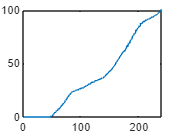

plot(T.Percentage)

vOut = VideoWriter('liquidVideoBinary.mp4', 'MPEG-4');
vOut.FrameRate = V.FrameRate;

V.CurrentTime = 0;

open(vOut);

for i = 1:V.NumFrames

    img = readFrame(V);

    BW = im2gray(img) > 68;
    BW = imopen(BW, strel('disk', 3, 0));
    BW = imclose(BW, strel('disk', 3, 0));
    BW = imfill(BW, 'holes');
    BW = ~BW;

    frame = imfuse(img, BW, 'montage');
    writeVideo(vOut, frame);

end

close(vOut);

vIn = VideoReader('shuttle.avi');
vOut = VideoWriter('shuttle_clip.mp4', 'MPEG-4');
vOut.FrameRate = vIn.FrameRate;

open(vOut);

for i = 1:118

    img = readFrame(vIn);
    writeVideo(vOut, img);

end

close(vOut);